% bathymetry data map 
[A,R] = readgeoraster('hsb.tif','OutputType','double');
%Create a map. First, create map axes by specifying the latitude and longitude limits of the data. Then, display the data as a surface using the geoshow function. Apply a colormap appropriate for elevation data using the demcmap function.
latlim = R.LatitudeLimits;
lonlim = R.LongitudeLimits;

nlatlim = [53.67, 54.015];
nlonlim =[2.17, 2.83];

[B,RB] = geocrop(A,R,nlatlim,nlonlim);

usamap(nlatlim,nlonlim);
geoshow(B,RB,'DisplayType','surface');
%demcmap(A);


% reading hornsea shapefile
S = shaperead('horn3shape.shp');

% use: hornshape = S.Geometry to see what bits r called
% boundary coordinates
x1 = S.X

x1 =     2.7483    2.7933    2.7933    2.4121    2.3954    2.3954    2.1974    2.1974    2.2263    2.5455    2.6813    2.7483       NaN


y1 = S.Y

y1 =    53.8159   53.6895   53.6895   53.8065   53.8075   53.8075   53.9896   53.9896   53.9887   53.9785   54.0011   53.8159       NaN


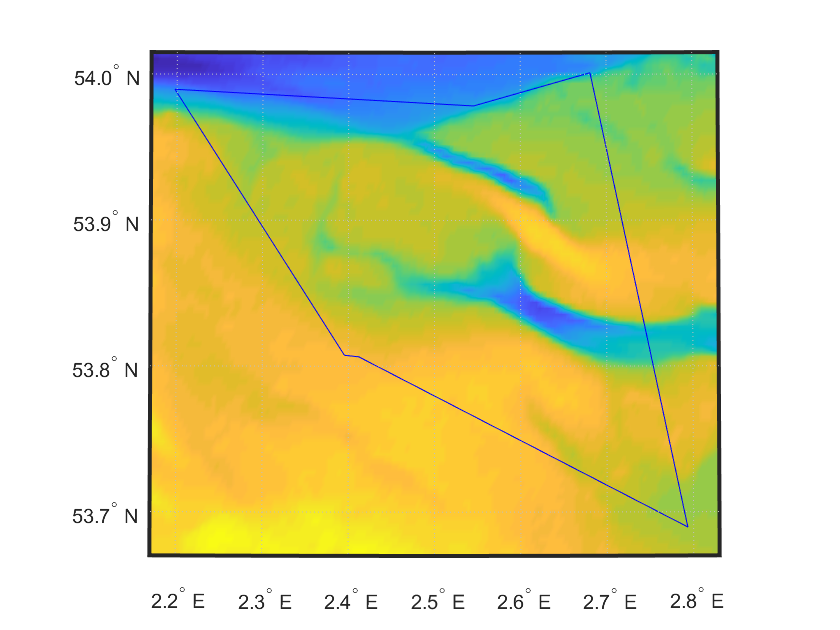

% showing the map
geoshow(y1,x1);
hold off 